clear; clc; close all;

syms x1 x2 x3 x4  u
% parametros del sistema
ma=0.6; % masa brazo [kg]
mp=0.2; % masa pendulo [kg]
la=1.1600e-1; % largo del brazo [m]
lp=3.0001e-1; % largo del pendulo [m]
j0=(ma*la^2)/3; %inercia brazo [kg m^2]
g=9.8;  % gravedad [m/s^-2]
j1=(mp*lp^2)/3; % inercia pendulo [kg m^2]
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Ts=0.01;% tiempo de muestreo


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% x1: angulo del brazo (\phi)
% x2: velocidad angular del brazo (\dot\phi)
% x3: angulo del pendulo (\theta)
% x4: velocidad angular del pendulo (\dot\theta)
% u: torque del motor 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sistema no lineal pendulo
a1=((ma+mp)/3)*la^2;  %alfa
a2=(mp*lp^2)/3;       %beta
a3=(mp*la*lp)/2;      %lambda
a4=(mp*g*lp)/2;       %delta
den=((a1*a2)-a3^2)+((a2^2+a3^2)*sin(x3)^2);
% campo vectorial
f1=x2;
f2=((a2*a3*(sin(x3)^2-1)*sin(x3)*x2^2)-...
    (2*a2^2*cos(x3)*sin(x3)*x2*x4)+(a2*a3*sin(x3)*x4^2)-...
    (a3*a4*cos(x3)*sin(x3))+(a2*u))/den;
f3=x4;
f4=((a2*(a1+a2*sin(x3)^2)*cos(x3)*sin(x3)*x2^2)+...
    (2*a2*a3*(1-sin(x3)^2)*sin(x3)*x2*x4)-...
    (a3^2*cos(x3)*sin(x3)*x4^2)+(a4*(a1+a2*sin(x3)^2)*sin(x3))-...
    (a3*cos(x3)*u))/den;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

f = [f1; f2; f3; f4];


## 2. LINEALIZACIÓN DEL SISTEMA

A_sym = jacobian(f, [x1; x2; x3; x4]);
B_sym = jacobian(f, u);

ref=0;
x1ss=0;
x2ss=0;
x3ss= ref;
x4ss=0;
uss=(3*g*la*mp*sin(2*ref))/8;

A = double(subs(A_sym, [x1, x2, x3, x4, u], [x1ss x2ss x3ss x4ss uss]));
B = double(subs(B_sym, [x1, x2, x3, x4, u], [x1ss x2ss x3ss x4ss uss]));
C = [1 0 0 0]; 
D = 0;

%% 3. DISEÑO DEL CONTROLADOR POR ASIGNACIÓN DE POLOS (POLE PLACEMENT)
% Construcción de las matrices aumentadas (6x6) con doble integrador
Aa = [A,  zeros(4, 1);
      -C, 0];
Ba = [B;
      0];

zeta = 1;tsdes = 3;
wn = 4.6 / (zeta * tsdes);
polos_dominantes = roots([1, 2*zeta*wn, wn^2]);
polos_secundarios = [-0.3, -6, -5];
polos_deseados = [polos_dominantes', polos_secundarios];

% Polos más lejanos 
sistReferencia=tf([0 0 1],[1 2*zeta*wn wn^2])


sistReferencia =
 
            1
  ---------------------
  s^2 + 3.067 s + 2.351
 
Continuous-time transfer function.
Model Properties


%polosz=[pole(sistReferencia)' -2 -3 -4];

%polosz=[pole(sistReferencia)' -1 -6 -5];
polosz=[pole(sistReferencia)' -0.3 -6 -5]

polosz =   -1.5333 - 0.0000i  -1.5333 + 0.0000i  -0.3000 + 0.0000i  -6.0000 + 0.0000i  -5.0000 + 0.0000i


K = acker(Aa, Ba, polosz);
disp(K);

   -0.0034   -0.0044   -0.4993   -0.0465    0.0007




%%% Se usa Ka como en tu código original para la ganancia aumentada
K1 = acker(Aa, Ba, polos_deseados);
disp(K1);

   -0.0034   -0.0044   -0.4993   -0.0465    0.0007



%% Control pendulo de Furuta en CoppeliaSim
% Se recomienda que sea en un archivo .m y no en un liveScript
% por la velocidad de ejecución
% A. Pantoja, Departamento de Electrónica, Universidad de Nariño
clear estados control controlmed
%clear all
close all
%% Inicialización de objeto CoppeliaSim y sincronización con planta 
vrep=remApi('remoteApi');

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


vrep.simxFinish(-1);
clientID=vrep.simxStart('127.0.0.1',19997,true,true,5000,5)

clientID = 0

r = 180*pi/180; 
re= [];
ban = 0;
ban2 = 0;
b = 0;
sws = [];
%% Parámetros del controlador Swing-up
params.mp = mp;
params.lp = lp;
params.g = g;
params.k = 2.0;
Gain = 1;
if (clientID>-1)
    disp('connected to remote API Server');
    vrep.simxSynchronous(clientID,false);    % modo sincronización
    % Obtencion de handles de los objetos en la simulación 
    [~,motor]=vrep.simxGetObjectHandle(clientID,'motor',vrep.simx_opmode_blocking); %motor - pos brazo
    [~,sensor1]=vrep.simxGetObjectHandle(clientID,'Potenciometro',vrep.simx_opmode_blocking); %sensor pos péndulo
    [~,sensorvb]=vrep.simxGetObjectHandle(clientID,'rotating',vrep.simx_opmode_blocking); %sensor vel brazo
    [~,sensorvp]=vrep.simxGetObjectHandle(clientID,'pendulum',vrep.simx_opmode_blocking);%sensor vel pendulo
    % Primera lectura de sensores modo streaming
    [~,angb]=vrep.simxGetJointPosition(clientID,motor,vrep.simx_opmode_streaming);
    [~,angp]=vrep.simxGetJointPosition(clientID,sensor1,vrep.simx_opmode_streaming);
    [~,~,angularb]=vrep.simxGetObjectVelocity(clientID,sensorvb,vrep.simx_opmode_streaming);
    [~,~,angularp]=vrep.simxGetObjectVelocity(clientID,sensorvp,vrep.simx_opmode_streaming);
    [~,torqm]=vrep.simxGetJointForce(clientID,motor,vrep.simx_opmode_streaming);
    vrep.simxPauseSimulation(clientID,vrep.simx_opmode_oneshot);    %pausa simulación
    pause(2);
 %% Inicialización de variables   
    % refv=[200*pi/180 180*pi/180 100*pi/180]; % Referencias
    % ref=refv(1);
    %ref=90*pi/180;
    Tsim=70;            % Tiempo total de la simulación
    Ts=0.1;               % Periodo de muestreo
    Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
    e_ant=0;
    int_err=0;
 %% Main Control Cycle
    vrep.simxStartSimulation(clientID,vrep.simx_opmode_oneshot);
     for i=1:Ns
             tic % Inicia conteo de tiempo para asegugar muestreo
             %vrep.simxStartSimulation(clientID,vrep.simx_opmode_oneshot);
             %vrep.simxSynchronousTrigger(clientID);
         % letura de estados: x1=pos_brazo[rad], x2=pos_pend[rad], x3=vel_brazo[rad/s], x4=vel_pend[rad/s]
             [~,angb]=vrep.simxGetJointPosition(clientID,motor,vrep.simx_opmode_buffer); 
             g(i) = angb;
             angb = angb-floor(angb/(2*pi))*2*pi; % Lectura de 0 a 2*pi sin saltos por periodicidad
             
             [~,angp]=vrep.simxGetJointPosition(clientID,sensor1,vrep.simx_opmode_buffer);
             [~,~,angularb]=vrep.simxGetObjectVelocity(clientID,sensorvb,vrep.simx_opmode_buffer);
             [~,~,angularp]=vrep.simxGetObjectVelocity(clientID,sensorvp,vrep.simx_opmode_buffer);
             [~,torqm]=vrep.simxGetJointForce(clientID,motor,vrep.simx_opmode_buffer);
             
             % if angularb < -1000
             %    b = 1;
             % end
             % if angularb > 1000
             %    b = 0;
             % end
             % if b == 1
             %     angb = angb-2*pi;
             % end
             % Estados medidos en un vector
             x=[angb; angularb(3); angp; angularp(1)]; % estados medidos
            % Aproximacion trapezoidal de la integral de error
             e_act=r-angb; %error angulo del brazo
            
            % Cálculo del torque de control
            y = x(1);
            re(i) = r;   
            % Ganancias interpoladas según el ángulo del brazo (y)
        
            hp(i) = abs(angp-floor(angp/(2*pi))*2*pi);
            if abs(angp-floor(angp/(2*pi))*2*pi) < deg2rad(25) || abs(angp-floor(angp/(2*pi))*2*pi) > deg2rad(335)  && abs(angularp(1)) < deg2rad(200) %&& angb >  deg2rad(50) 
                if ban == 0;
                    r = angb; %deg2rad(50);
                    ban = 1;
                    Gain = 1.5;
                    ki = 1;
                end
                ki = ki+1;
                if ki == 60
                    Gain = 1.4;
                    ban2 = 1;
                end
                % Salida medida: ángulo del brazo (phi)
                 e = r - y;              % Error
                 int_err = int_err + Ts * e;  % Integrador
                 u_c = -Gain*K * [x; int_err];
                 sw = 1;
                 u_c = min(u_c, 0.8);
                 u_c = max(u_c, -0.8);
            else
                 ban = 0;
                 ban2 = 0;
                 u_c = 0.7*swing_up_energy_controller(x, params);
                 %u_c = 0.3*cos(i*0.25);
                 int_err = 0; % Resetear el integrador
                 sw = 0;
             end

            % Aplicación de torque a motor en CoppeliaSim
             if u_c>0
                vel=99; torqap=u_c;
             else
                vel=-99; torqap=-u_c;
             end
             vrep.simxSetJointForce(clientID,motor,torqap,vrep.simx_opmode_blocking);
             vrep.simxSetJointTargetVelocity(clientID,motor,vel,vrep.simx_opmode_blocking);
            % Almacenamiento de vectores y actualización de memoria
            sws(i) =sw;
            e_ant=e_act;
            control(i)=u_c;
            controlmed(i)=torqm;
            %control(i)=vf;
            estados(i,:)=x;

            % Cambio de referencia
            if ban2 == 1
                if i==round(30/Ts)
                    r=140*pi/180;
                elseif i==round(45/Ts)
                    r=50*pi/180;
                end
            end
            toc
            pause(max(Ts-toc, 0));  % Espera el tiempo para garantizar muestreo uniforme      
     end 
    vrep.simxStopSimulation(clientID,vrep.simx_opmode_blocking); % para simulación
    vrep.simxFinish(-1);
end

connected to remote API Server


Elapsed time is 0.163889 seconds.
Elapsed time is 0.096712 seconds.
Elapsed time is 0.093348 seconds.
Elapsed time is 0.097455 seconds.
Elapsed time is 0.110326 seconds.
Elapsed time is 0.084833 seconds.
Elapsed time is 0.081763 seconds.
Elapsed time is 0.092503 seconds.
Elapsed time is 0.089460 seconds.
Elapsed time is 0.085180 seconds.
Elapsed time is 0.092310 seconds.
Elapsed time is 0.085691 seconds.
Elapsed time is 0.094516 seconds.
Elapsed time is 0.087695 seconds.
Elapsed time is 0.092621 seconds.
Elapsed time is 0.086836 seconds.
Elapsed time is 0.080926 seconds.
Elapsed time is 0.090328 seconds.
Elapsed time is 0.094437 seconds.
Elapsed time is 0.084415 seconds.
Elapsed time is 0.084818 seconds.
Elapsed time is 0.079193 seconds.
Elapsed time is 0.086947 seconds.
Elapsed time is 0.083278 seconds.
Elapsed time is 0.081745 seconds.
Elapsed time is 0.086166 seconds.
Elapsed time is 0.081523 seconds.
Elapsed time is 0.079183 seconds.
Elapsed time is 0.085040 seconds.
Elapsed time i

vrep.delete();

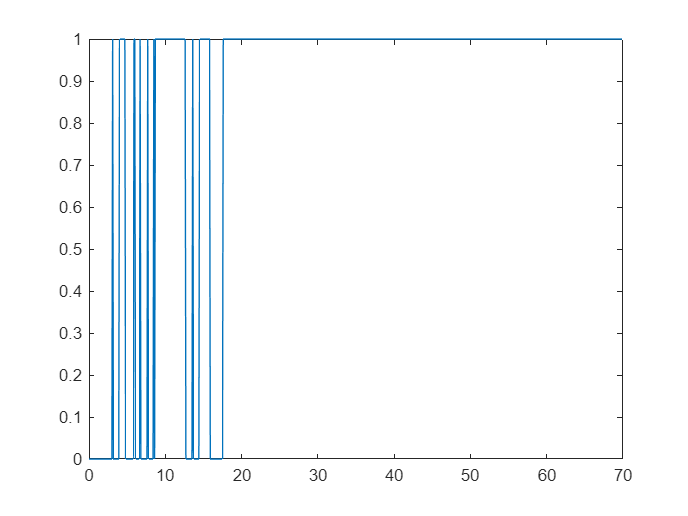

tdisc=0:Ts:Ns*Ts-Ts;
figure;
plot(tdisc, sws)

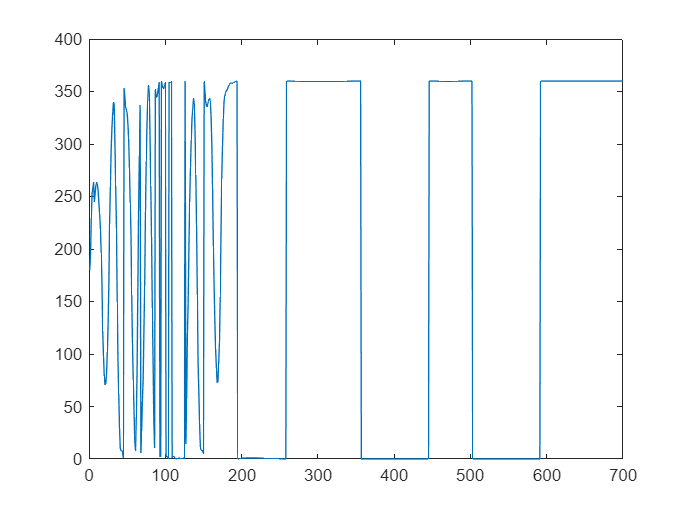

figure;
plot(hp*180/pi)

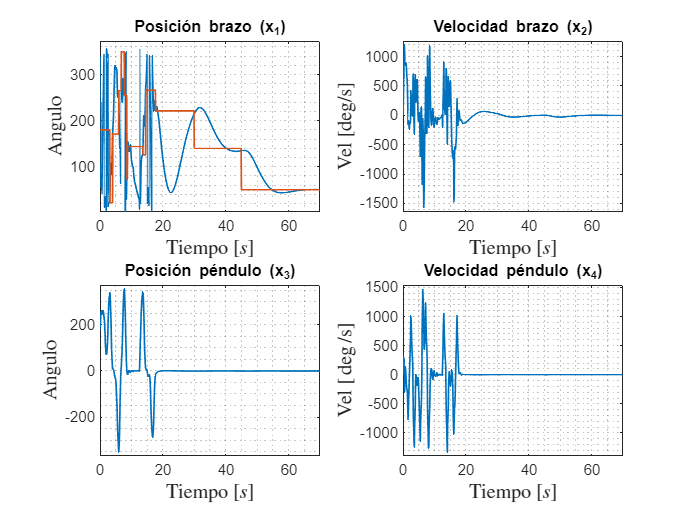


figure
subplot(2,2,1);
plot(tdisc,estados(:,1)*180/pi, 'LineWidth', 1);
hold on;
plot(tdisc, re*180/pi, 'LineWidth', 1);
grid minor;
ylabel("Angulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Posición brazo (x_1)')
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,1)*180/pi), 1.05*max(estados(:,1)*180/pi)])

subplot(2,2,2);
plot(tdisc,estados(:,2)*180/pi, 'LineWidth', 1);
ylabel("Vel [deg/s]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Velocidad brazo (x_2)')
grid minor;
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,2)*180/pi), 1.05*max(estados(:,2)*180/pi)])

subplot(2,2,3);
plot(tdisc,estados(:,3)*180/pi, 'LineWidth', 1);
ylabel("Angulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Posición péndulo (x_3)')
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,3)*180/pi), 1.05*max(estados(:,3)*180/pi)])
grid minor;

subplot(2,2,4);
plot(tdisc,estados(:,4)*180/pi, 'LineWidth', 1);
title('Velocidad péndulo (x_4)')
grid minor;
ylabel("Vel [$\deg$/s]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,4)*180/pi), 1.05*max(estados(:,4)*180/pi)])

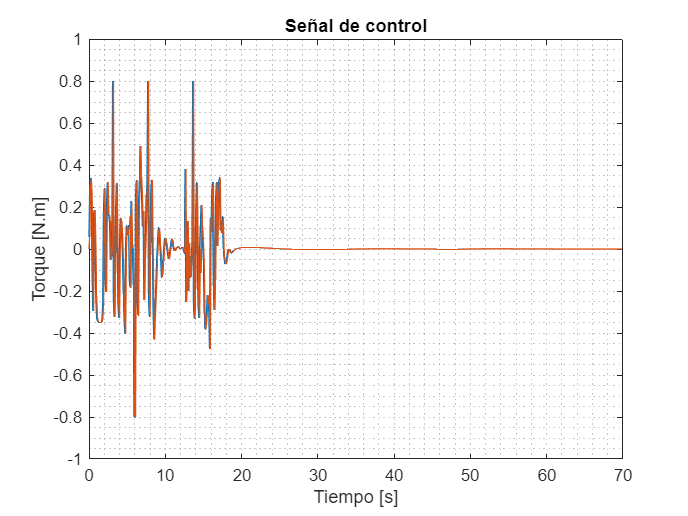


%%%%%%%%
figure
plot(tdisc,control, tdisc,-controlmed);
xlabel('Tiempo [s]');
ylabel('Torque [N.m]');
title('Señal de control')
grid minor;

ITAE y Energía

% Calcular el error
error_signal = ref - estados(:,1);
error_signal2 = 0-estados(:,3);
ITAE = trapz(tdisc, tdisc .* (abs(error_signal)+abs(error_signal2)));
disp(['ITAE: ', num2str(ITAE)]);

ITAE: 0      42.2597733      84.5195465      126.779327      169.039093      211.298859      253.558655      295.818512      338.078186      380.338013      422.597717      464.857574       507.11731      549.377075      591.637024      633.896606      676.156372       718.41626      760.676025       802.93573      845.195435        887.4552      929.715149      971.975037      1014.23462      1056.49438      1098.75415      1141.01416      1183.27405      1225.53333      1267.79321      1310.05322      1352.31274      1394.57239      1436.83252      1479.09204      1521.35205      1563.61182      1605.87146      1648.13123      1690.39087      1732.65063       1774.9104      1817.17065       1859.4303      1901.69006      1943.95007      1986.20959      2028.46924      2070.72925      2112.98877      2155.24854       2197.5083      2239.76807      2282.02832       2324.2876       2366.5481      2408.80713      2451.06665      2493.32715      2535.58643      2577.84668      2620.10645 


y = estados(:, 1)*180/pi;
error_signal = abs(ref - y');
ITAE_LQR = trapz(tdisc, tdisc .* (error_signal+error_signal2));
ITAE = sum(tdisc.*error_signal)*Ts;
disp(['ITAE: ', num2str(ITAE)]);

ITAE: 231566.0469



% Calcular de la energía
ene_signal = control.^2;
ENE = trapz(tdisc, tdisc .* abs(ene_signal));
disp(['Energia: ', num2str(ENE)]);

Energia: 8.4779


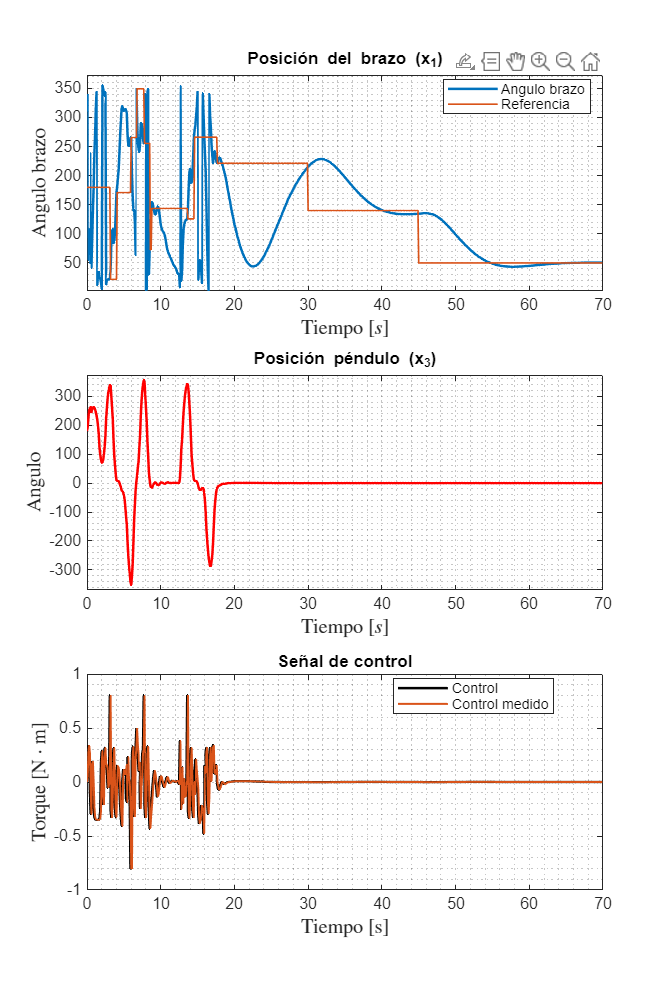

figure('Position', [50, 50, 1200, 1800]);  % [x, y, width, height]

subplot(3,1,1);
plot(tdisc, estados(:,1)*180/pi, 'LineWidth', 1.5);
hold on;
plot(tdisc, re*180/pi, 'LineWidth', 1);
grid minor;
ylabel("Angulo brazo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title("Posición del brazo (x_1)");
legend("Angulo brazo", "Referencia", "Location", "best");
xlim([0, Ns*Ts]);
ylim([1.05*min(estados(:,1)*180/pi), 1.05*max(estados(:,1)*180/pi)]);

subplot(3,1,2);
plot(tdisc, estados(:,3)*180/pi, 'r', 'LineWidth', 1.5);
ylabel("Angulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Posición péndulo (x_3)')
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,3)*180/pi), 1.05*max(estados(:,3)*180/pi)])
grid minor;

subplot(3,1,3);
plot(tdisc, control, 'k', 'LineWidth', 1.5); hold on;
plot(tdisc, -controlmed, 'LineWidth', 1.2);
grid minor;
xlabel("Tiempo [s]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
ylabel("Torque [N$\cdot$m]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title("Señal de control", "FontWeight", "bold", "Interpreter", "latex");
legend("Control", "Control medido", "Location", "best");
xlim([0, Ns*Ts]);